rosshutdown

Shutting down global node /matlab_global_node_26389 with NodeURI http://192.168.218.155:55055/


%connect 1 den
setenv('ROS_MASTER_URI','http://192.168.218.180:11311')
% 2 mig
setenv('ROS_IP','192.168.218.155')
% 3 den mig
rosinit('http://192.168.218.180:11311','NodeHost','192.168.218.155')

Initializing global node /matlab_global_node_95598 with NodeURI http://192.168.218.155:55084/


% 2 mig
%setenv('ROS_IP','192.168.218.155')

% 3 den mig
%rosinit('http://192.168.218.180:11311','NodeHost','192.168.218.155')

% Load the image
img = imread('Testmap1.png');


% Convert the image to grayscale
gray_img = rgb2gray(img);

% Convert the grayscale image to a binary image
binary_img = imbinarize(gray_img);
    
% Create a binary occupancy map from the binary image
scale_factor = 500;   %500 pixels pr. meter
map = binaryOccupancyMap(binary_img,scale_factor);

% Create a new binary occupancy map from the resized matrix
new_map = binaryOccupancyMap(map);

% Show the map
show(new_map);

%Create points
NumNodes = 300;
prmComplex = mobileRobotPRM(new_map,NumNodes);
prmComplex.ConnectionDistance = 0.6;
show(prmComplex)

%Define start location
startLocation1 = [0.1 0.1];
endLocation1 = [1.5 1];
path1 = findpath(prmComplex,startLocation1,endLocation1)

path1 =     0.1000    0.1000
    0.0377    0.0766
    0.2130    0.6045
    0.3954    0.7364
    0.8235    0.8390
    1.0468    0.9072
    1.4503    1.0215
    1.5000    1.0000


show(prmComplex)


endLocation2 = [1.5 1.9];
path2 = findpath(prmComplex,endLocation1,endLocation2);
show(prmComplex)

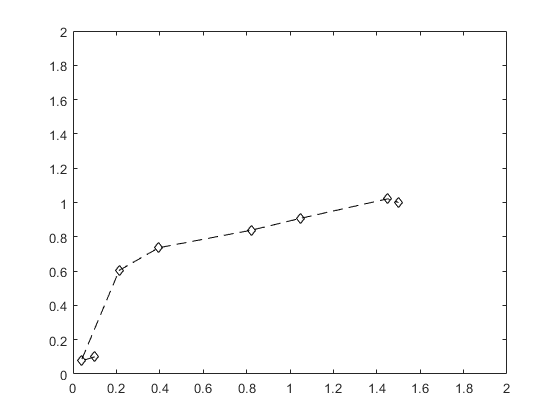


robotInitialLocation = path1(1,:);
robotGoal = path1(end,:);

initialOrientation = 0;

robotCurrentPose = [robotInitialLocation initialOrientation]';
robot = differentialDriveKinematics("TrackWidth", 1, "VehicleInputs", "VehicleSpeedHeadingRate");

%1st path
figure
plot(path1(:,1), path1(:,2),'k--d')
xlim([-0 2])
ylim([-0 2])

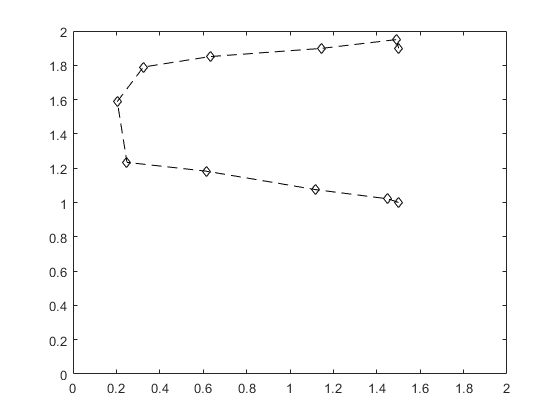


%2nd path
figure
plot(path2(:,1), path2(:,2),'k--d')
xlim([-0 2])
ylim([-0 2])

%Controller 
controller = controllerPurePursuit;
controller.Waypoints = path1;
controller.DesiredLinearVelocity = 0.4;
controller.MaxAngularVelocity = 1;
controller.LookaheadDistance = 0.2;

goalRadius = 0.1;
distanceToGoal = norm(robotInitialLocation - robotGoal);

% TIL TURTLEBOT - DEFINITIVT!
vel_pub = rospublisher('/cmd_vel');
velmsg = rosmessage(vel_pub);
odomSub = rossubscriber("/odom","DataFormat","struct");

% Initialize the simulation loop
sampleTime = 0.1;
vizRate = rateControl(1/sampleTime);

% Initialize the figure
figure

% Determine vehicle frame size to most closely represent vehicle with plotTransforms
frameSize = robot.TrackWidth/5;
s = path1(1,:)

s =     0.1000    0.1000



current_pose = robotCurrentPose

current_pose =     0.1000
    0.1000
         0


r_pose = receive(odomSub);

init_position = [r_pose.pose.pose.position.x r_pose.pose.pose.position.y]

init_position =    10.9241   -6.5724


r_init_orientation = [r_pose.pose.pose.orientation.x r_pose.pose.pose.orientation.y r_pose.pose.pose.orientation.z r_pose.pose.pose.orientation.w]

r_init_orientation =          0         0   -0.1248    0.9922



eul = quat2eul(r_init_orientation);
init_orientation = eul(3);
init_pose = [init_position init_orientation]';

theta = eul(3);
rot_mat = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

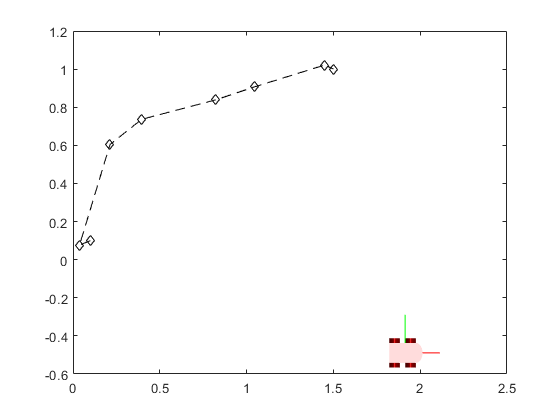

while( distanceToGoal > goalRadius )
    
    % Compute the controller outputs, i.e., the inputs to the robot
    [v, omega] = controller(robotCurrentPose);
    velmsg.Angular.Z = omega;	% Angular velocity (rad/s)
    velmsg.Linear.X = v;
    send(vel_pub,velmsg);

    
    % Get the robot's velocity using controller inputs
    r_pose = receive(odomSub);
    position_x = r_pose.pose.pose.position.x;
    position_y = r_pose.pose.pose.position.y;
    position = [position_x position_y];
    x = r_pose.pose.pose.orientation.x;
    y = r_pose.pose.pose.orientation.y;
    z = r_pose.pose.pose.orientation.z;
    w = r_pose.pose.pose.orientation.w;
    eul = quat2eul([x y z w]);
    orientation = eul(3);

    robotCurrentPose = [position orientation]' - init_pose;
    %vel = derivative(robot, robotCurrentPose, [v omega]);
    
    % Update the current pose
    %robotCurrentPose = robotCurrentPose + vel*sampleTime; 
    s(end+1,:) = robotCurrentPose(1:2);
    % Re-compute the distance to the goal
    distanceToGoal = norm(robotCurrentPose(1:2) - robotGoal(:));
    
    % Update the plot
    hold off
    
    % Plot path each instance so that it stays persistent while robot mesh
    % moves
    plot(path1(:,1), path1(:,2),"k--d")
    hold all
    
    % Plot the path of the robot as a set of transforms
    plotTrVec = [robotCurrentPose(1:2); 0];
    plotRot = axang2quat([0 0 1 robotCurrentPose(3)]);
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", frameSize);
    light;

   
    waitfor(vizRate);
end